addpath('HHT_EWS')

df_fold = csvread('HHT_EWS/traj_data.csv',1);
df_hopf_tot = csvread('HHT_EWS/traj_data_hopf.csv',1);
df_foldwoNoise = csvread('HHT_EWS/traj_data_fold_woNoise.csv',1);

df_hopf = df_hopf_tot(1:50000,:);

[imf_hopf,residual_hopf,info_hopf] = emd(df_hopf(:,3),'Interpolation','pchip');

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        3     |     0.073371   |  SiftMaxRelativeTolerance
      2      |        3     |      0.19401   |  SiftMaxRelativeTolerance
      3      |        6     |      0.15654   |  SiftMaxRelativeTolerance
      4      |        2     |      0.13146   |  SiftMaxRelativeTolerance
      5      |        1     |      0.18308   |  SiftMaxRelativeTolerance
      6      |        2     |     0.080019   |  SiftMaxRelativeTolerance
      7      |        2     |     0.049056   |  SiftMaxRelativeTolerance
      8      |        2     |     0.034631   |  SiftMaxRelativeTolerance
      9      |        4     |     0.025464   |  SiftMaxRelativeTolerance
     10      |        3     |     0.021606   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


% Perform ensemble EMD
Ne = 500;
sigma_e = 0.5;
rng(101);

avg_trials = [];
for trial_ =1:1:Ne
    noise_ = randn(50000,1).*sigma_e;
    imf_ = emd(df_hopf(:,3) + noise_, 'Interpolation', 'pchip');
    
    
    % add on to running avg
    if trial_ == 1
        avg_trials = imf_;
    end
    if trial_ >1
        current_N  = trial_-1;
        avg_trials = avg_trials + imf_;        
    end
end

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030127   |  SiftMaxRelativeTolerance
      2      |        2     |     0.067618   |  SiftMaxRelativeTolerance
      3      |        2     |     0.066902   |  SiftMaxRelativeTolerance
      4      |        2     |     0.083657   |  SiftMaxRelativeTolerance
      5      |        3     |     0.088082   |  SiftMaxRelativeTolerance
      6      |        1     |      0.16008   |  SiftMaxRelativeTolerance
      7      |        2     |     0.059449   |  SiftMaxRelativeTolerance
      8      |        2     |     0.037868   |  SiftMaxRelativeTolerance
      9      |        2     |     0.074646   |  SiftMaxRelativeTolerance
     10      |        3     |      0.18975   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.
Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.032361   |  SiftMaxRelativeTolerance


imf_hopf_eemd = avg_trials./Ne;

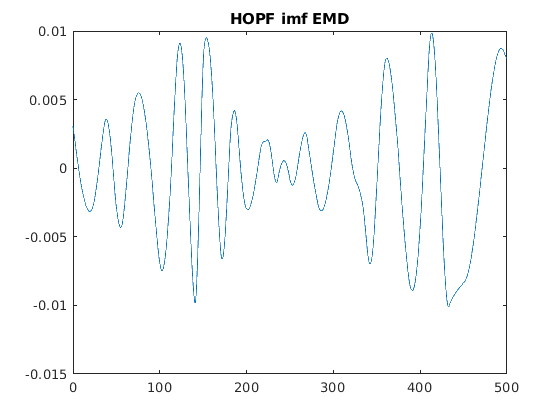

clf
plot(df_hopf(:,2), imf_hopf(:,9))
title("HOPF imf EMD")

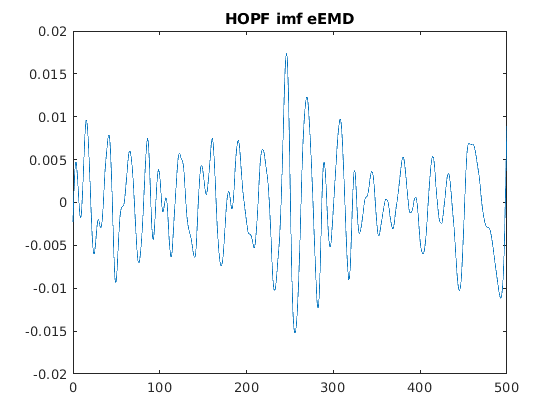

clf
plot(df_hopf(:,2), imf_hopf_eemd(:,9))
title("HOPF imf eEMD")

[hs_hopf,f,t,imfinsf_hopf,imfinse_hopf] = hht(imf_hopf,100);
[hs_hopf_eemd,f_hopf_eemd,t,imfinsf_hopf_eemd,imfinse_hopf_eemd] = hht(imf_hopf_eemd,100);

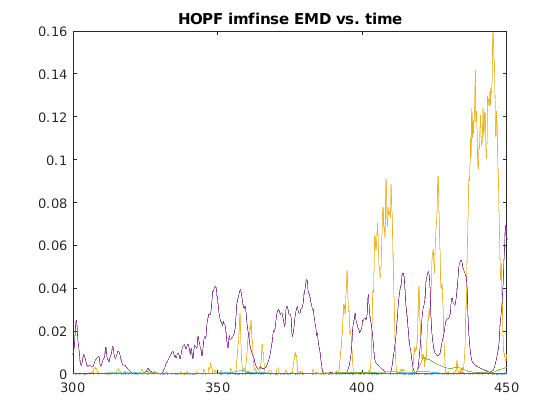

clf
plot(t, imfinse_hopf(:,2:end))
title("HOPF imfinse EMD vs. time")
xlim([300,450])

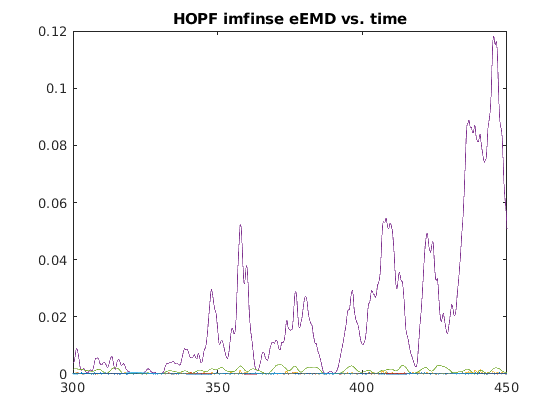

clf
plot(t, imfinse_hopf_eemd(:,3:end))
title("HOPF imfinse eEMD vs. time")
xlim([300,450])

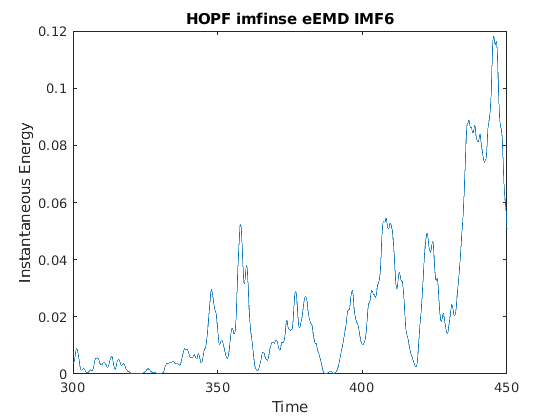

% IMF 10 has a very significant energy increase as 
% the bifurcation is approached
clf 
plot(t, imfinse_hopf_eemd(:,6))
title("HOPF imfinse eEMD IMF6")
xlabel("Time")
ylabel("Instantaneous Energy")
xlim([300,450])

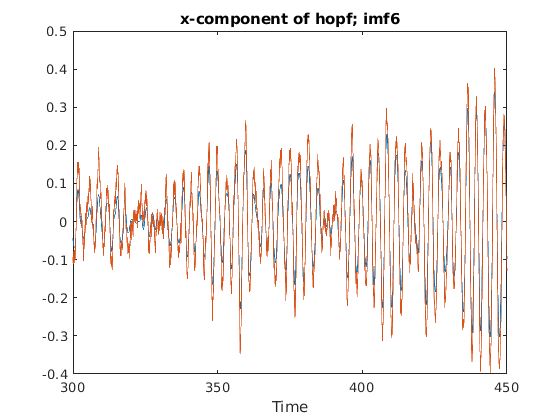

clf
plot(t, imf_hopf_eemd(:,6))
hold on
plot(t, df_hopf(:,3))
title("x-component of hopf; imf6")
xlim([300,450])
xlabel("Time")

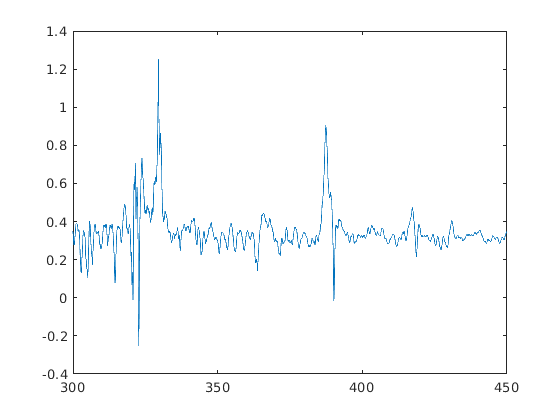

clf
plot(t, imfinsf_hopf_eemd(:,6))
xlim([300,450])